## Homework 2.1

f = @(x) 1 - exp(x-4) - exp(-(x-2).^2);

### a. Plot function f and determine number of real solutions

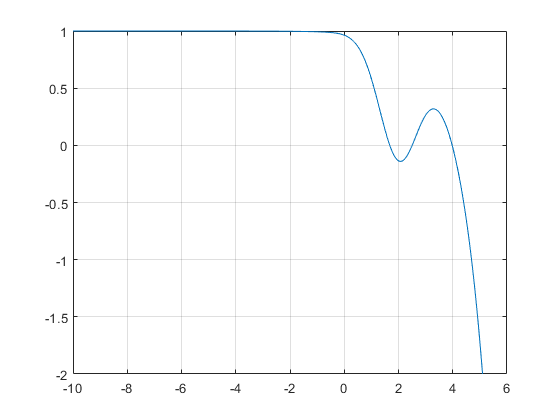

x = linspace(-10, 10, 1000);

figure();
plot(x, f(x));
grid on;
ylim([-2, 1]);

The number of real solutions is: 3

### b. Bisection method run

#### b.1 Interval [0, 5]

a = 0;
b = 5;

tol = 10e-3;

[x x_iter] = bisection(f, a, b, tol);

fprintf('Interval [0, 5] - x: %g', x);

Interval [0, 5] - x: 1.66992

display(x_iter);

x_iter =     2.5000    1.2500    1.8750    1.5625    1.7188    1.6406    1.6797    1.6602    1.6699


#### b.2 Interval [1, 6]

a = 1;
b = 6;

tol = 10e-3;

[x x_iter] = bisection(f, a, b, tol);

fprintf('Interval [1, 6] - x: %g', x);

Interval [1, 6] - x: 3.97852

display(x_iter);

x_iter =     3.5000    4.7500    4.1250    3.8125    3.9688    4.0469    4.0078    3.9883    3.9785


#### b.3 Interval [1, 5]

a = 1;
b = 5;

tol = 10e-3;

[x x_iter] = bisection(f, a, b, tol);

fprintf('Interval [1, 5] - x: %g', x);

Interval [1, 5] - x: 3.97656

display(x_iter);

x_iter =     3.0000    4.0000    3.5000    3.7500    3.8750    3.9375    3.9688    3.9844    3.9766


#### b.4 Interval [-1, 5]

a = -1;
b = 5;

tol = 10e-3;

[x x_iter] = bisection(f, a, b, tol);

fprintf('Interval [-1, 5] - x: %g', x);

Interval [-1, 5] - x: 1.67773

display(x_iter);

x_iter =     2.0000    0.5000    1.2500    1.6250    1.8125    1.7188    1.6719    1.6953    1.6836    1.6777


As we can see we have found only 2 of the 3 zeros. In order to find all the 3 zeros we have to select thiner intervals around the specific zeros. All the 4 intervals selected contain all the zeros. We must have intervals which contain only one zero.

Functions:

function [x, x_iter] = bisection(f, a, b, tol)
    Nmax = ceil(log((b-a)/tol)/log(2));
    
    for i = 1:Nmax
        x_iter(i) = (b+a)/2;
        
        if f(x_iter(i)) == 0
            break;
        end
        
        if f(x_iter(i))*f(a) < 0
            b = x_iter(i);
        else
            a = x_iter(i);
        end
    end
    
    x = x_iter(end);
end